
% to do
% 1) get 2-way, 3-way bar graphs
%   - scatter ball-only vs rest?
% 2) commonality analysis
% 3) debug venn.m

% why sometimes PVAF(A)> PVAF(AUB)? due to cross validation? then for training data,
% alway PVAF(A)<PVAF(AUB)

% dependence: axisEqual applytofig4keynote

load run_glm.mat

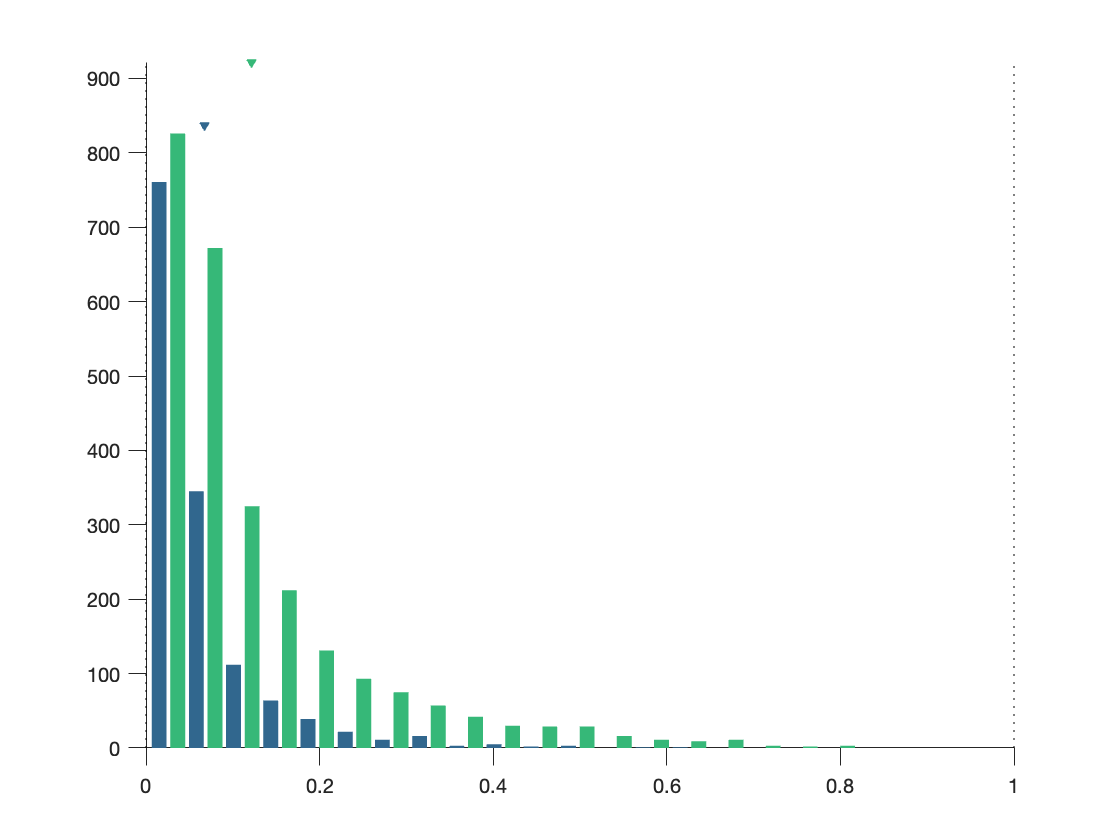

% histogram of R2 for full model (train) to check if R2>0
% separate histogram for vis/occ (# neurons are slightly different)

id_full_model=1;
PVAF_train_vis=PVAF_train_vis(:,id_full_model);
PVAF_train_occ=PVAF_train_occ(:,id_full_model);

% plotting spec
nBin=20;
b=linspace(min([PVAF_train_vis(:);PVAF_train_occ(:)]),max([PVAF_train_vis(:);PVAF_train_occ(:)]),nBin);
cmap=viridis(2);

% main
figure; hold all;
i_bin=1;
plot_histogram(PVAF_train_vis,b,i_bin,cmap);
i_bin=2;
plot_histogram(PVAF_train_occ,b,i_bin,cmap);
drawnow; pause(0.5);

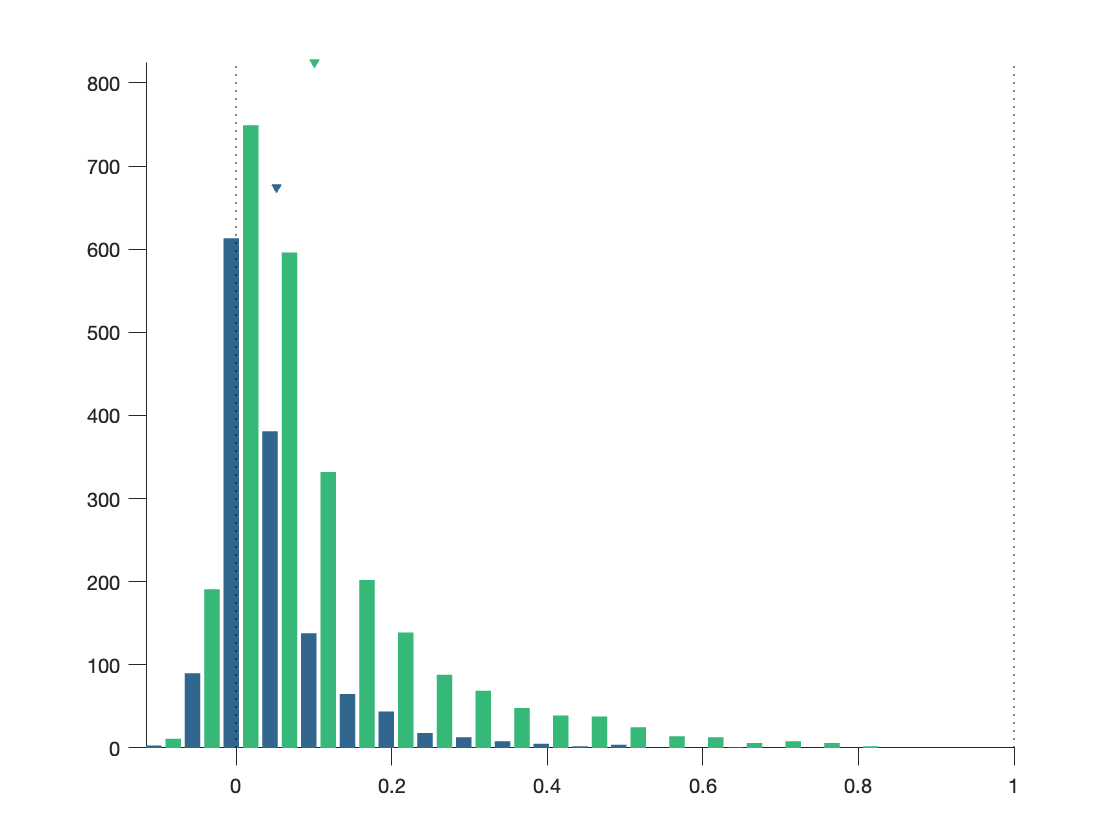

% histogram of R2 for full model
% separate histogram for vis/occ (# neurons are slightly different)

id_full_model=1;
PVAF_vis=PVAF_model_vis(:,id_full_model);
PVAF_occ=PVAF_model_occ(:,id_full_model);

% plotting spec
nBin=20;
b=linspace(min([PVAF_vis(:);PVAF_occ(:)]),max([PVAF_vis(:);PVAF_occ(:)]),nBin);
cmap=viridis(2);

% main
figure; hold all;
i_bin=1;
plot_histogram(PVAF_vis,b,i_bin,cmap);
i_bin=2;
plot_histogram(PVAF_occ,b,i_bin,cmap);
drawnow; pause(0.5);

## plot PVAF vis vs occ (to choose eg neuron)

idx_occ=D.neural_idx_global.occ.neural_responses;
idx_vis=D.neural_idx_global.vis.neural_responses;

figure; hold all;

for i=1:length(idx_occ) % occ is bigger
    tmpId=find(idx_vis==idx_occ(i));
    if ~isempty(tmpId)
        tmpX=PVAF_vis(tmpId);
        tmpY=PVAF_occ(i);
        
        plot(tmpX,tmpY,'ko');
        
        if abs(tmpX-0.4)<0.05 & abs(tmpY-0.4)<0.05
            disp(idx_occ(i));
        end
%         if abs(tmpX-0.5)<0.05 & abs(tmpY-0.5)<0.05
%             disp(idx_occ(i));
%         end
%         if abs(tmpX-0.1)<0.05 & abs(tmpY-0.5)<0.05
%             disp(idx_occ(i));
%         end
%         if abs(tmpX-0.5)<0.05 & abs(tmpY-0.1)<0.05
%             disp(idx_occ(i));
%         end
    end
end

   1968



   2157



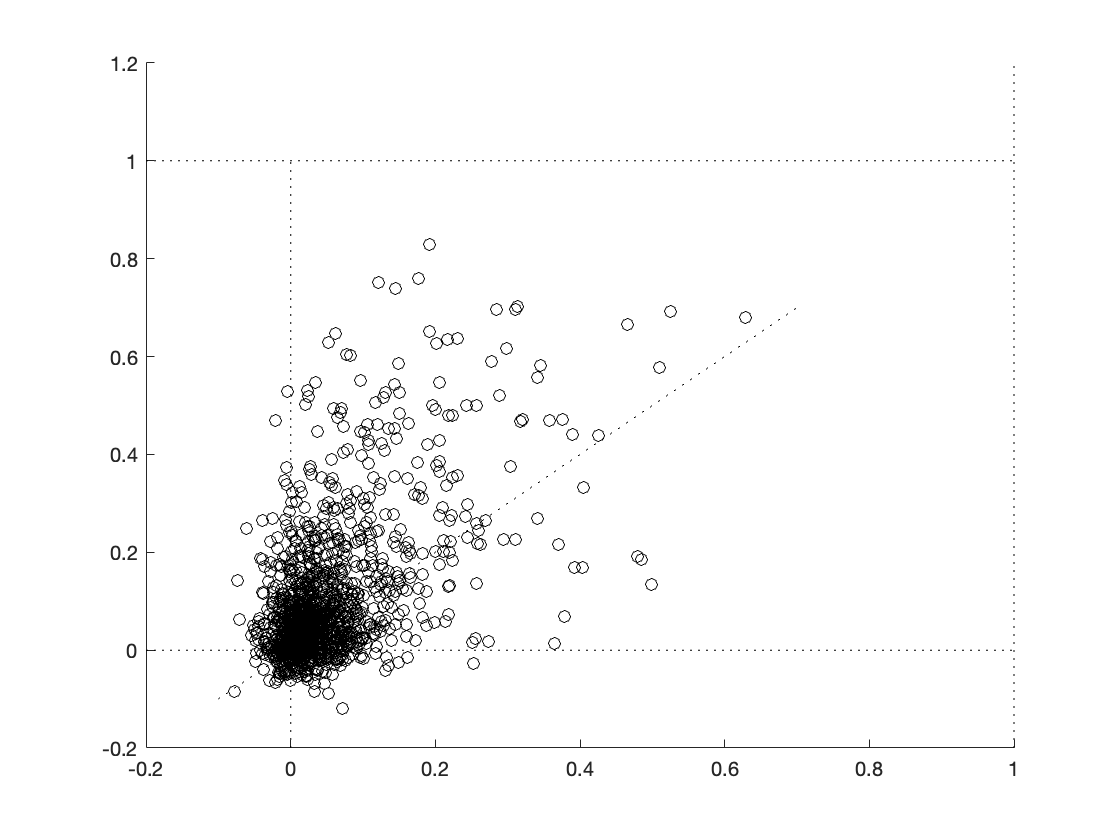


plotIdentity(gca);
plotVertical(gca,0,[]); plotVertical(gca,1,[]);
plotHorizon(gca,0,[]); plotHorizon(gca,1,[]);
drawnow; pause(0.5);

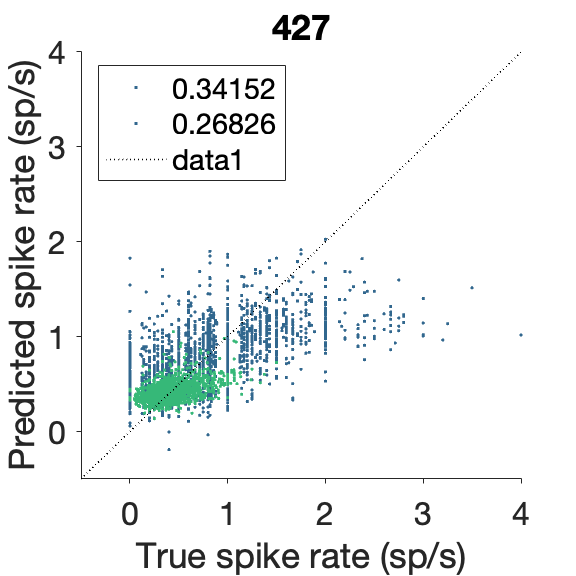

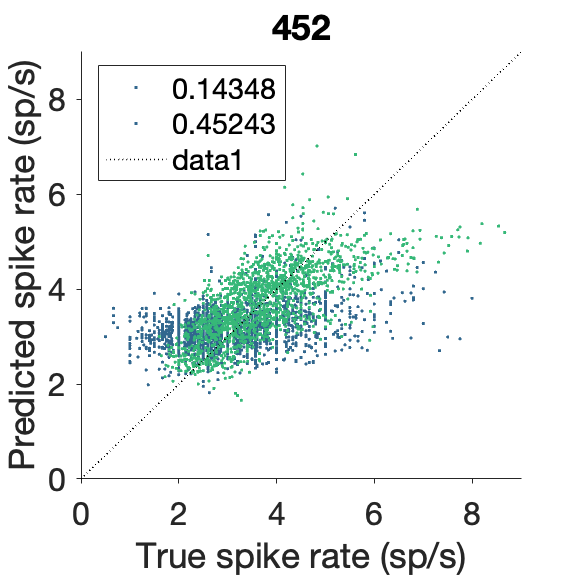

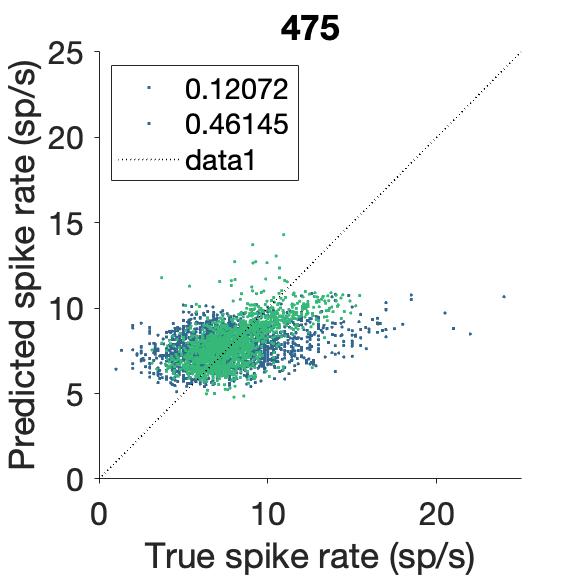

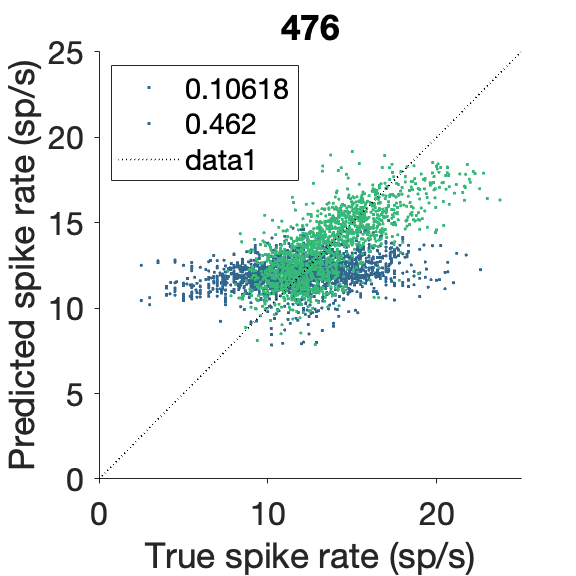

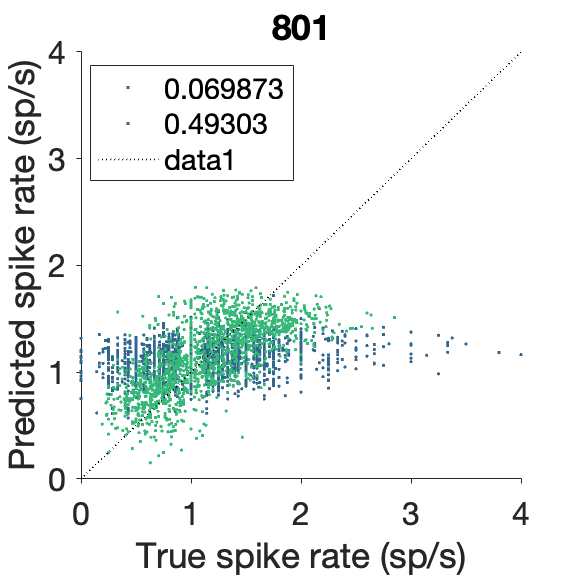

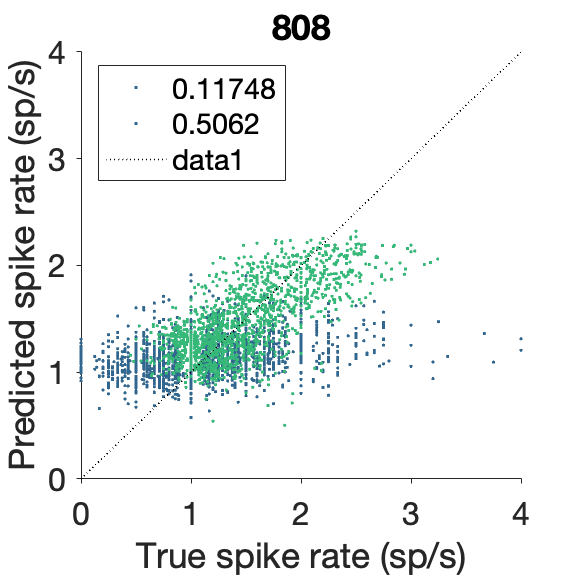

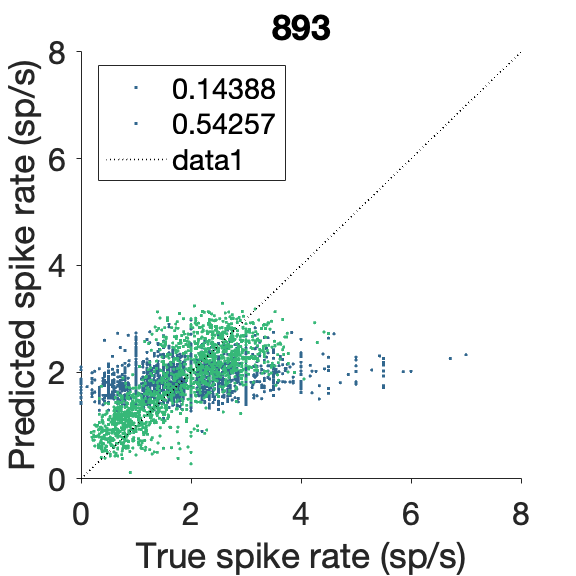

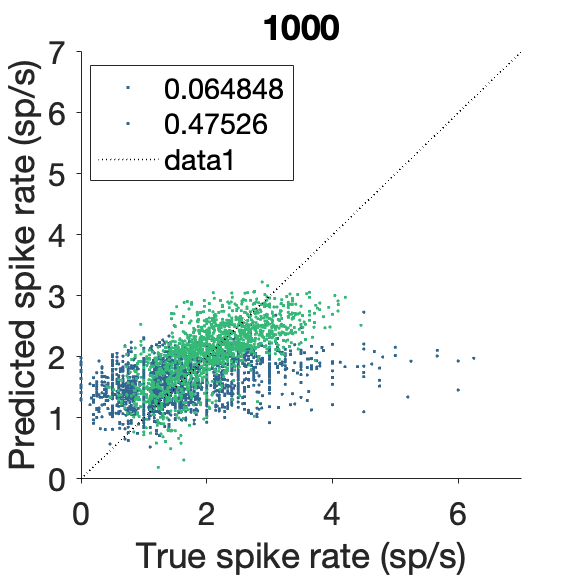

% plot example neuron's predicted vs actual responses (full model)
eg_neuron_id=[427;452;475;476;801;808;893;1000;1014;1107;1172;1244;1251;1451;1491;1545;1836;2105;1968;2157];
% 1014; 1593; 2628];
for i=1:length(eg_neuron_id)
    plot_eg_glm_fit(eg_neuron_id(i));
    
    title(eg_neuron_id(i));
    
    legend({num2str(PVAF_vis(eg_neuron_id(i)==idx_vis)),...
        num2str(PVAF_occ(eg_neuron_id(i)==idx_occ))},...
        'location','best');
    
    drawnow;
    axisEqual;
    set(gca,'tickdir','out');
    plotIdentity(gca);
    ylabel('Predicted spike rate (sp/s)');
    xlabel('True spike rate (sp/s)');
    applytofig4keynote;
end


drawnow; pause(0.5);
% plot PSTH or spatial modulation?

## plot PVAF bar

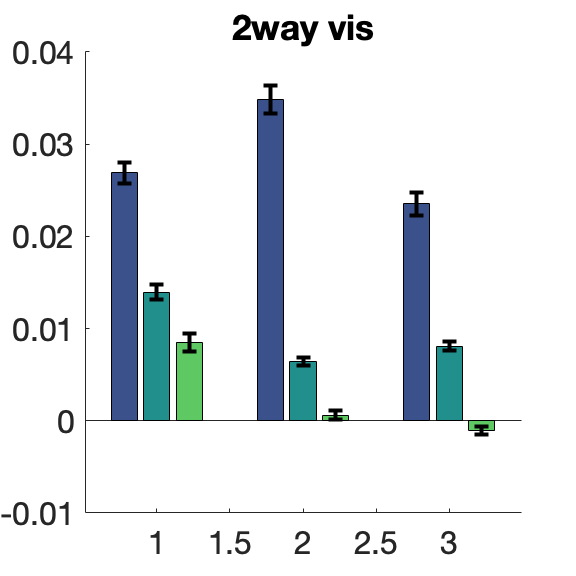

% set up indices
id_median=0; % if 0, mean

sets={'ball','eye','hand'};
labels={'ball','eye','hand','ball & eye','ball & hand','eye & hand','full'}; % A, B, C, A&B, A&C, B&C and A&B&C.
colors=[1 0 0; 0 0.7 0; 0 0 1];
id_individual_area=[11 10 9]; % 'ball','eye','hand'
id_union=[4 5 6 1]; % 'ball & eye','ball & hand','eye & hand','full'
% 1 full
% 2 -pos 7 +pos
% 3 -k 8 +k
% 4 -hand (ball&eye) 9 +hand
% 5 -eye (ball&hand) 10 +eye
% 6 -ball (eye&hand) 11 +ball

% reorganize by new indices
V=PVAF_model_vis(:,[id_individual_area id_union]);
O=PVAF_model_occ(:,[id_individual_area id_union]);

n_neuron_vis=size(V,1);
n_neuron_occ=size(O,1);

n_labels=length(labels);
cmap=viridis(n_labels); % parula(n_labels);
% variance partioning
% intersection
VI=[V(:,1)+V(:,2)-V(:,4) ... % ball&eye
    V(:,1)+V(:,3)-V(:,5) ... % ball&hand
    V(:,2)+V(:,3)-V(:,6) ... % eye&hand
    V(:,7)+sum(V(:,1:3),2)-sum(V(:,4:6),2) % ball&eye&hand
    ];
OI=[O(:,1)+O(:,2)-O(:,4) ... % ball&eye
    O(:,1)+O(:,3)-O(:,5) ... % ball&hand
    O(:,2)+O(:,3)-O(:,6) ... % eye&hand
    O(:,7)+sum(O(:,1:3),2)-sum(O(:,4:6),2)]; % ball&eye&hand

% 2-way: {ball_eye, ball_hand, eye_hand}
PVAF_vis2=[]; PVAF_occ2=[];
PVAF_vis2{1,1}=[V(:,1)-VI(:,1)... % ball - eye
    V(:,2)-VI(:,1)... % eye - ball
    VI(:,1)]; % ball & eye
PVAF_vis2{2,1}=[V(:,1)-VI(:,2)... % ball - hand
    V(:,3)-VI(:,2)... % hand - ball
    VI(:,2)]; % ball & hand
PVAF_vis2{3,1}=[V(:,2)-VI(:,3)... % eye - hand
    V(:,3)-VI(:,3)... % hand - eye
    VI(:,3)]; % eye & hand
PVAF_occ2{1,1}=[O(:,1)-OI(:,1)... % ball - eye
    O(:,2)-OI(:,1)... % eye - ball
    OI(:,1)]; % ball & eye
PVAF_occ2{2,1}=[O(:,1)-OI(:,2)... % ball - hand
    O(:,3)-OI(:,2)... % hand - ball
    OI(:,2)]; % ball & hand
PVAF_occ2{3,1}=[O(:,2)-OI(:,3)... % eye - hand
    O(:,3)-OI(:,3)... % hand - eye
    OI(:,3)]; % eye & hand

% 3-way: ball, eye, hand (7:A,B,C,AB,AC,BC,ABC)
PVAF_vis3=[V(:,1)-VI(:,1)-VI(:,2)+VI(:,4)... % 1
    V(:,2)-VI(:,1)-VI(:,3)+VI(:,4)... 
    V(:,3)-VI(:,2)-VI(:,3)+VI(:,4)...  
    VI(:,1)-VI(:,4)... % 2
    VI(:,2)-VI(:,4)...
    VI(:,3)-VI(:,4)...
    VI(:,4)]; % 3
PVAF_occ3=[O(:,1)-OI(:,1)-OI(:,2)+OI(:,4)... % 1
    O(:,2)-OI(:,1)-OI(:,3)+OI(:,4)... 
    O(:,3)-OI(:,2)-OI(:,3)+OI(:,4)...  
    OI(:,1)-OI(:,4)... % 2
    OI(:,2)-OI(:,4)...
    OI(:,3)-OI(:,4)...
    OI(:,4)]; % 3

% cmap
n_labels3=size(PVAF_vis3,2);
cmap3=cividis(n_labels3); % 7
n_labels2=size(PVAF_occ2{1},2);
cmap2=viridis(n_labels2); % 3
% % check triangle inequlaity
% find(V(:,4)<(V(:,1)+V(:,2)))
% compute mean/sem
sum_fun={@(x)nanmean(x,1),@(x)nanmedian(x,1)};
std_fun={@(x)sem(x,1,'omitnan'),@(x)mad(x,1,1)}; % @(x)nanmean(abs(x-nanmean(x,1)),1)};
% mean: 2-way
mPVAF_vis2=cellfun(sum_fun{id_median+1},PVAF_vis2,'UniformOutput',false);
mPVAF_occ2=cellfun(sum_fun{id_median+1},PVAF_occ2,'UniformOutput',false);
% mean: 3-way
mPVAF_vis3=sum_fun{id_median+1}(PVAF_vis3);
mPVAF_occ3=sum_fun{id_median+1}(PVAF_occ3);
% sem: 2-way
sPVAF_vis2=cellfun(std_fun{id_median+1},PVAF_vis2,'UniformOutput',false);
sPVAF_occ2=cellfun(std_fun{id_median+1},PVAF_occ2,'UniformOutput',false);
% MAD: 3-way
sPVAF_vis3=std_fun{id_median+1}(PVAF_vis3);
sPVAF_occ3=std_fun{id_median+1}(PVAF_occ3);
% bar graphs
x2=[1:n_labels2];
x3=[1:n_labels3];

% 2way vis
mPVAF_vis2_mat=cell2mat(mPVAF_vis2); % [12,13,23 x A-B,B-A,A&B]
figure; ha; title('2way vis');
bar_error(x2,mPVAF_vis2_mat,cell2mat(sPVAF_vis2),cmap2);
applytofig4keynote;

drawnow; pause(0.5);

% 3way vis
figure; ha; title('3way vis');

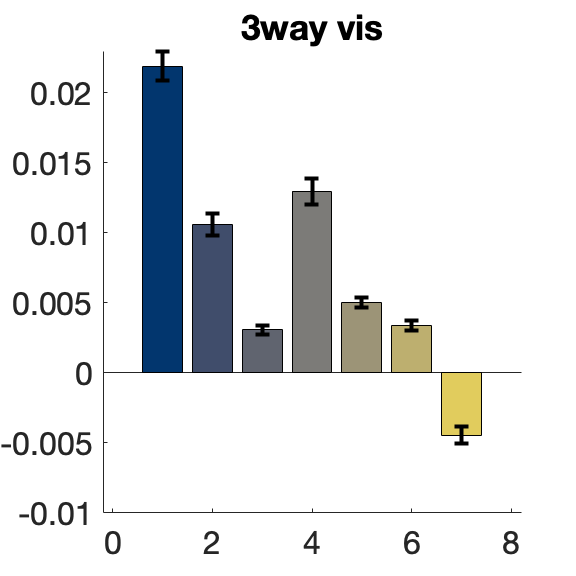

b=bar(x3,mPVAF_vis3);
b.FaceColor = 'flat';
b.CData = cmap3;
errorbar(x3,mPVAF_vis3,sPVAF_vis3,'LineStyle','none','Color','k','linewidth',2);
applytofig4keynote;

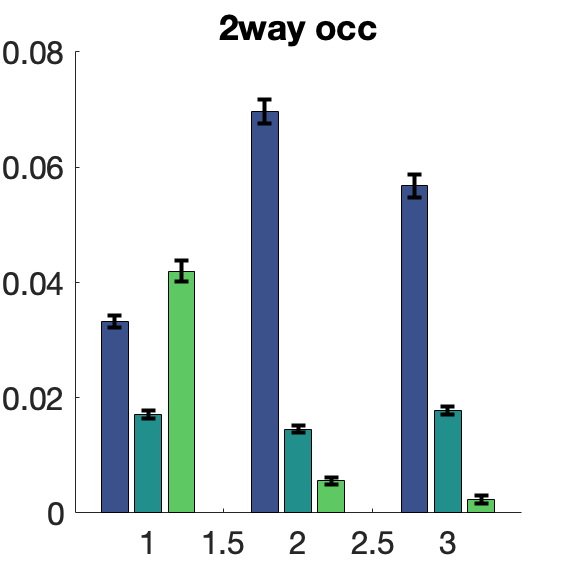

drawnow; pause(0.5);

% 2way occ
mPVAF_occ2_mat=cell2mat(mPVAF_occ2);
figure; ha; title('2way occ');
bar_error(x2,mPVAF_occ2_mat,cell2mat(sPVAF_occ2),cmap2);
applytofig4keynote;

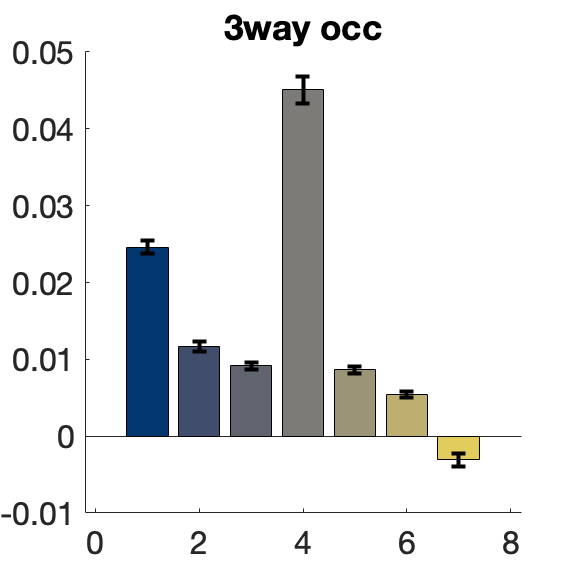

drawnow; pause(0.5);

% 3way occ
figure; ha; title('3way occ');
b=bar(x3,mPVAF_occ3);
b.FaceColor = 'flat';
b.CData = cmap3;
errorbar(x3,mPVAF_occ3,sPVAF_occ3,'LineStyle','none','Color','k','linewidth',2);
applytofig4keynote;

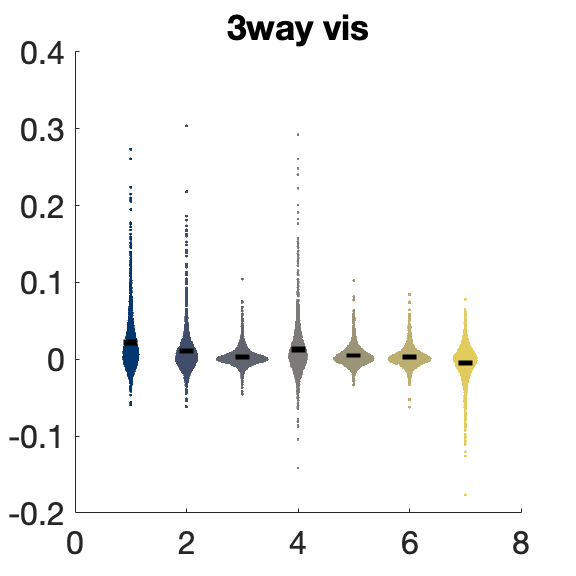

drawnow; pause(0.5);

% Swarmchart
% 3way vis
x3_2d=repmat(x3,size(PVAF_vis3,1),1); % 1385 x 7
cmap3_2d=repmat(cmap3,1,1,size(PVAF_vis3,1)); % 7 x 3 x 1385
cmap3_2d=shiftdim(cmap3_2d,1); % 3 x 1385 x 7
figure; ha; title('3way vis');
b=swarmchart(x3_2d(:),PVAF_vis3(:),1,cmap3_2d(:,:)','marker','.');
errorbar(x3,mPVAF_vis3,sPVAF_vis3,'LineStyle','none','Color','k','linewidth',2);
applytofig4keynote;

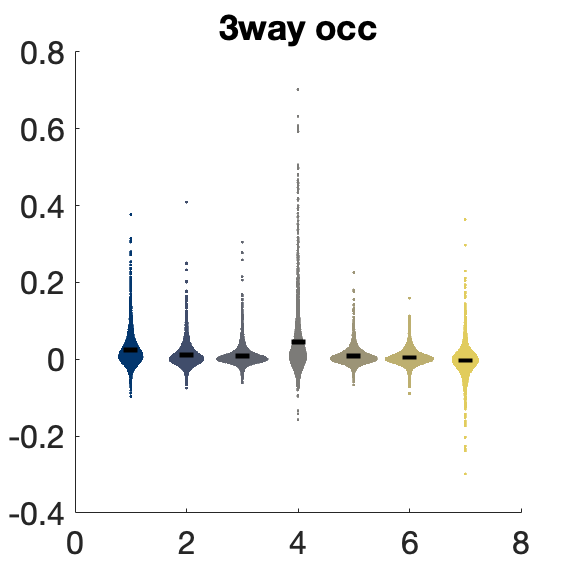

drawnow; pause(0.5);
% 3way occ
x3_2d=repmat(x3,size(PVAF_occ3,1),1); % 1385 x 7
cmap3_2d=repmat(cmap3,1,1,size(PVAF_occ3,1)); % 7 x 3 x 1385
cmap3_2d=shiftdim(cmap3_2d,1); % 3 x 1385 x 7
figure; ha; title('3way occ');
b=swarmchart(x3_2d(:),PVAF_occ3(:),1,cmap3_2d(:,:)','marker','.');
errorbar(x3,mPVAF_occ3,sPVAF_occ3,'LineStyle','none','Color','k','linewidth',2);
applytofig4keynote;

drawnow; pause(0.5);

% STAT
disp('visible');

visible


disp(mPVAF_vis3);

    0.0219    0.0106    0.0031    0.0130    0.0050    0.0034   -0.0044



disp(size(PVAF_vis3));

     1     7



[p,h,stats]=signrank(PVAF_vis3(:,1),PVAF_vis3(:,4))

p = 5.8926e-11

h = logical
   1


stats = struct with fields:
          zval: 6.5464
    signedrank: 577362



disp('occluded');

occluded


disp(mPVAF_occ3);

    0.0246    0.0117    0.0091    0.0451    0.0086    0.0054   -0.0031



disp(size(PVAF_occ3));

     1     7



[p,h,stats]=signrank(PVAF_occ3(:,1),PVAF_occ3(:,4))

p = 2.5217e-25

h = logical
   1


stats = struct with fields:
          zval: -10.3984
    signedrank: 1267015


[p,h,stats]=signrank(PVAF_occ3(:,1),PVAF_occ3(:,2))

p = 5.7315e-55

h = logical
   1


stats = struct with fields:
          zval: 15.6153
    signedrank: 2249115



% save
save PVAF_allocentric.mat PVAF_vis3 PVAF_occ3

return;

% swarmplot
X=repmat(x,n_neuron_vis,1);
figure; ha;
for i_label=1:size(X,2)
    swarmchart(X(:,i_label),PVAF_vis3(:,i_label),'.','Markerfacecolor',cmap3(i_label,:));
end
applytofig4keynote

X=repmat(x,n_neuron_occ,1);
figure; ha;
for i_label=1:size(X,2)
    swarmchart(X(:,i_label),PVAF_occ3(:,i_label),'.','Markerfacecolor',cmap3(i_label,:));
end
applytofig4keynote
return;

% venn diagram
% TBD: debug (maybe due to cross validation, PVAF(full model)<PVAF(reduced) sometimes

% for venn diagram
PVAF_vis=[V(:,1:3)...
    VI];
PVAF_occ=[O(:,1:3)...
    OI];

figure;
vennfig_vis = venn(nanmean(PVAF_vis(1:3),1),nanmean(PVAF_vis(4:end),1));
applytofig4keynote

figure;
vennfig_occ = venn(nanmean(PVAF_occ(1:3),1),nanmean(PVAF_occ(4:end),1));
applytofig4keynote
% scatter: ball-only vs rest with ball-related
PVAF_vis
% clustering? PCA?





function plot_histogram(x,b,i,cmap)

n=2;
markersize=4;
barWidth=0.4;

h=histogram(x,b);
Xval    = h.BinEdges + h.BinWidth*0.5 +h.BinWidth*(i-(n+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
Xval    = Xval(1:end-1);Yval    = h.Values; delete(h);
hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',cmap(i,:),'EdgeColor','none');
axis tight;
% plot mean
maxYlim=max(ylim);
plot(mean(x),1.1*maxYlim,'color',cmap(i,:),'markerfacecolor',cmap(i,:),'marker','v','markersize',markersize);

plotVertical(gca,0,[]); plotVertical(gca,1,[]);

% xlim([-0.05 1.05]);
set(gca,'xtick',0:0.2:1,'tickdir','out','ticklength',[0.02 0.02]); % ,'ytick',0:3:20
pause(0.1);


end